% 时间序列预测ARIMA模型 - 股票价格预测案例
clc; clear; close all;
disp('============================================================');

disp('         时间序列预测ARIMA模型 - 股票价格预测案例');

         时间序列预测ARIMA模型 - 股票价格预测案例


disp('============================================================');


%% 第一步：数据生成与加载
disp(' ');

disp('1. 数据生成与加载');

1. 数据生成与加载


disp('------------------------------');

------------------------------



% 生成模拟股票价格数据
function df = generate_stock_data(start_date, periods, initial_price)
    rng(42); % 设置随机种子，保证结果可重复
    
    % 创建日期索引 - 确保生成periods个日期
    dates = datetime(start_date):days(1):datetime(start_date)+days(periods-1);
    % 强制确保日期数量正确
    if length(dates) ~= periods
        dates = dates(1:periods);
    end
    
    % 生成价格序列：随机游走 + 微弱趋势 + 波动率变化
    returns = normrnd(0.001, 0.02, periods, 1);  % 日收益率（确保是periods行）
    trend = linspace(0, 0.5, periods)' / periods; % 微弱上升趋势
    volatility = 1 + 0.3 * sin(linspace(0, 4*pi, periods)'); % 波动率周期性变化
    
    returns = returns + trend;
    returns = returns .* volatility;
    
    % 计算累积价格 - 确保生成periods个价格
    prices = zeros(periods, 1);
    prices(1) = initial_price;
    for i = 2:periods
        prices(i) = prices(i-1) * (1 + returns(i));
    end
    
    % 计算对数收益率 - 确保与价格长度一致
    log_prices = log(prices);
    log_returns = [0; diff(log_prices)];  % 第一个收益率为0，后续为差分
    
    % 调试：检查各变量长度
    fprintf('调试信息：dates长度=%d, prices长度=%d, returns长度=%d\n', ...
        length(dates), length(prices), length(log_returns));
    
    % 创建表格（确保所有变量长度一致）
    df = table(dates', prices, log_returns, 'VariableNames', {'date', 'price', 'returns'});
end

% 生成数据
stock_data = generate_stock_data('2023-01-01', 180, 100);

调试信息：dates长度=180, prices长度=180, returns长度=180


fprintf('数据期间: %s 至 %s\n', ...
    datestr(stock_data.date(1), 'yyyy-mm-dd'), ...
    datestr(stock_data.date(end), 'yyyy-mm-dd'));

数据期间: 2023-01-01 至 2023-06-29


fprintf('数据点数: %d\n', height(stock_data));

数据点数: 180


fprintf('价格范围: %.2f - %.2f\n', ...
    min(stock_data.price), max(stock_data.price));

价格范围: 96.41 - 122.04



% 显示基本统计信息
disp(' ');

disp('数据基本统计:');

数据基本统计:


disp(table( ...
    mean(stock_data.price), std(stock_data.price), min(stock_data.price), max(stock_data.price), ...
    mean(stock_data.returns), std(stock_data.returns), min(stock_data.returns), max(stock_data.returns), ...
    'VariableNames', {'price_mean', 'price_std', 'price_min', 'price_max', ...
    'returns_mean', 'returns_std', 'returns_min', 'returns_max'}));

    price_mean    price_std    price_min    price_max    returns_mean    returns_std    returns_min    returns_max
    __________    _________    _________    _________    ____________    ___________    ___________    ___________
      110.16       5.1987       96.413       122.04       0.00079308      0.020048       -0.05409       0.061119  


%% 第二步：数据探索与可视化
disp(' ');

disp('2. 数据探索与可视化');

2. 数据探索与可视化


disp('------------------------------');

------------------------------


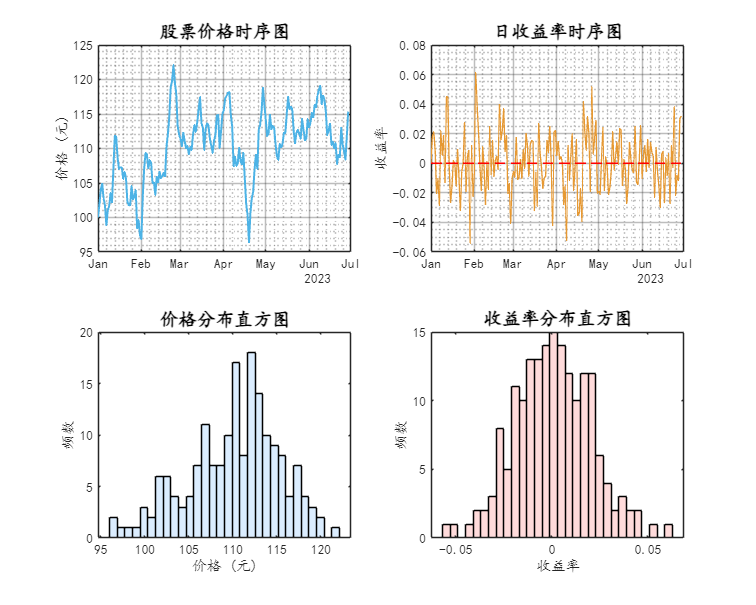


% 设置中文显示
set(groot, 'DefaultTextFontName', 'Kaiti');
set(groot, 'DefaultAxesFontName', 'Kaiti');

% 创建综合图表
figure('Position', [100, 100, 1000, 800]);

% 价格时序图
subplot(2, 2, 1);
plot(stock_data.date, stock_data.price, 'Color', [0.3 0.7 0.9], 'LineWidth', 1.5);
title('股票价格时序图', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('价格 (元)');
grid on;
grid minor;
set(gca, 'GridAlpha', 0.3);

% 收益率时序图
subplot(2, 2, 2);
plot(stock_data.date, stock_data.returns, 'Color', [0.9 0.6 0.2], 'LineWidth', 1);
hold on;
plot(stock_data.date, zeros(height(stock_data), 1), 'r--');
title('日收益率时序图', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('收益率');
grid on;
grid minor;
set(gca, 'GridAlpha', 0.3);

% 价格分布直方图
subplot(2, 2, 3);
histogram(stock_data.price, 30, 'FaceColor', [0.8 0.9 1], 'EdgeColor', 'k', 'FaceAlpha', 0.7);
title('价格分布直方图', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('价格 (元)');
ylabel('频数');

% 收益率分布直方图
subplot(2, 2, 4);
histogram(stock_data.returns, 30, 'FaceColor', [1 0.8 0.8], 'EdgeColor', 'k', 'FaceAlpha', 0.7);
title('收益率分布直方图', 'FontSize', 14, 'FontWeight', 'bold');
xlabel('收益率');
ylabel('频数');

% 计算一些描述性统计量
price_volatility = std(stock_data.returns) * sqrt(252);  % 年化波动率
cum_max = cummax(stock_data.price);
max_drawdown = min(stock_data.price ./ cum_max - 1);

fprintf('年化波动率: %.2f%%\n', price_volatility * 100);

年化波动率: 31.83%


fprintf('最大回撤: %.2f%%\n', max_drawdown * 100);

最大回撤: -21.00%


fprintf('收益率偏度: %.3f\n', skewness(stock_data.returns(~isnan(stock_data.returns))));

收益率偏度: 0.064


fprintf('收益率峰度: %.3f\n', kurtosis(stock_data.returns(~isnan(stock_data.returns))));

收益率峰度: 3.114


%% 第三步：平稳性检验
disp(' ');

disp('3. 平稳性检验');

3. 平稳性检验


disp('------------------------------');

------------------------------



% 详细ADF检验函数
function isStationary = detailedADFTest(data, titleStr)
    % 使用MATLAB的adftest进行单位根检验
    [h, pValue, ~, ~] = adftest(data, 'model','ARD');
    
    fprintf('\n%s ADF检验结果:\n', titleStr);
    fprintf('  p值: %.6f\n', pValue);
    
    if pValue <= 0.05
        fprintf('  结论: %s 是平稳的 (p值 = %.6f < 0.05)\n', titleStr, pValue);
        isStationary = true;
    else
        fprintf('  结论: %s 是非平稳的 (p值 = %.6f > 0.05)\n', titleStr, pValue);
        isStationary = false;
    end
end
% 检验原始价格序列
price_stationary = detailedADFTest(stock_data.price, '原始价格序列');

原始价格序列 ADF检验结果:
  p值: 0.025947
  结论: 原始价格序列 是平稳的 (p值 = 0.025947 < 0.05)



% 检验收益率序列
returns_stationary = detailedADFTest(stock_data.returns, '收益率序列');

收益率序列 ADF检验结果:
  p值: 0.001000
  结论: 收益率序列 是平稳的 (p值 = 0.001000 < 0.05)



% 如果价格序列非平稳，进行差分
if ~price_stationary
    stock_data.price_diff = [NaN; diff(stock_data.price)];
    diff_stationary = detailedADFTest(stock_data.price_diff(~isnan(stock_data.price_diff)), '价格一阶差分序列');
end

% 可视化平稳性
figure('Position', [100, 100, 1200, 900]);

% 原始价格
subplot(3,1,1);
plot(stock_data.date, stock_data.price, 'b-', 'LineWidth', 1.5);
title('原始价格序列', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('价格');
grid on;

% 收益率
subplot(3,1,2);
plot(stock_data.date, stock_data.returns, 'g-', 'LineWidth', 1);
yline(0, 'r--', 'Alpha', 0.7);
title('收益率序列(平稳)', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('收益率');
grid on;

disp(stock_data)

       date        price       returns  
    ___________    ______    ___________
    01-Jan-2023       100              0
    02-Jan-2023    101.87       0.018573
    03-Jan-2023    104.06       0.021188
    04-Jan-2023    104.92      0.0082491
    05-Jan-2023    102.77      -0.020639
    06-Jan-2023    101.71      -0.010409
    07-Jan-2023    98.872      -0.028301
    08-Jan-2023    101.07       0.021968
    09-Jan-2023    101.61      0.0053856
    10-Jan-2023    103.56       0.018941
    11-Jan-2023    102.24      -0.012825
    12-Jan-2023    106.94       0.044997
    13-Jan-2023    111.85       0.044902
    14-Jan-2023    111.68     -0.0015788
    15-Jan-2023    108.75      -0.026586
    16-Jan-2023    107.05      -0.015737
    17-Jan-2023    107.26       0.001944
    18-Jan-2023    107.27     9.3098e-05
    19-Jan-2023    105.62      -0.015475
    20-Jan-2023    106.63      0.0095303
    21-Jan-2023    105.68     -0.0089433
    22-Jan-2023    102.35       -0.03208
    23-Jan-2023 

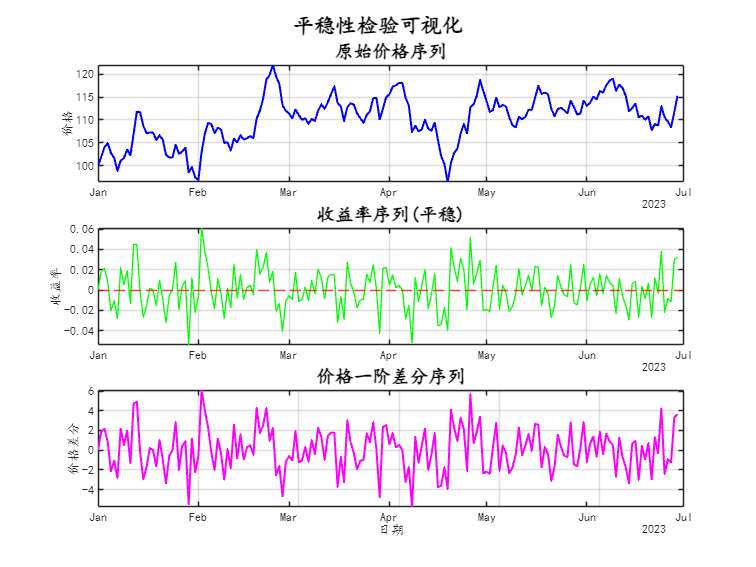

% 价格差分
subplot(3,1,3);
plot(stock_data.date, [0; diff(stock_data.price, 1)], 'm-', 'LineWidth', 1.5);
title('价格一阶差分序列', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('价格差分');
xlabel('日期');
grid on;

sgtitle('平稳性检验可视化', 'FontSize', 16, 'FontWeight', 'bold');

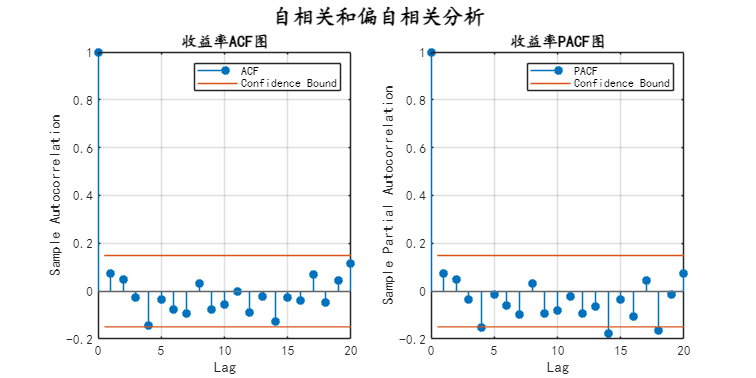

%% ========== 第四步：ACF和PACF分析 ==========

figure('Position', [100, 100, 1200, 600]);

% ACF图
subplot(1,2,1);
autocorr(stock_data.returns, 'NumLags', 20);
title('收益率ACF图', 'FontSize', 12, 'FontWeight', 'bold');
grid on;

% PACF图
subplot(1,2,2);
parcorr(stock_data.returns, 'NumLags', 20);
title('收益率PACF图', 'FontSize', 12, 'FontWeight', 'bold');
grid on;

sgtitle('自相关和偏自相关分析', 'FontSize', 16, 'FontWeight', 'bold');


% 分析ACF和PACF的截尾特征
function [suggested_p, suggested_q] = analyzeAcfPacf(data, maxLags)
    % 计算ACF和PACF
    [acfValues, lags, bounds] = autocorr(data, 'NumLags', maxLags);
[pacfValues, pacfLags, pacfBounds] = parcorr(data, 'NumLags', maxLags);
    
    n = length(data);
    confidenceInterval = 1.96 / sqrt(n);
    
    % 找出显著的滞后阶数
    significantAcf = find(abs(acfValues(2:end)) > confidenceInterval);
    significantPacf = find(abs(pacfValues(2:end)) > confidenceInterval);
    
    fprintf('显著的ACF滞后阶数: ');
    disp(significantAcf(1:min(5,length(significantAcf))));
    
    fprintf('显著的PACF滞后阶数: ');
    disp(significantPacf(1:min(5,length(significantPacf))));
    
    % 建议参数
    if ~isempty(significantPacf)
        suggested_p = min(3, max(significantPacf(1:min(3,length(significantPacf)))));
    else
        suggested_p = 0;
    end
    
    if ~isempty(significantAcf)
        suggested_q = min(3, max(significantAcf(1:min(3,length(significantAcf)))));
    else
        suggested_q = 0;
    end
    
    fprintf('建议ARIMA参数: p=%d, q=%d\n', suggested_p, suggested_q);
end

% 分析收益率序列
[suggested_p, suggested_q] = analyzeAcfPacf(stock_data.returns, 10);

显著的ACF滞后阶数: 显著的PACF滞后阶数:      4
建议ARIMA参数: p=3, q=0


%% ========== 第五步：ARIMA模型识别与选择 ==========

% 定义参数搜索范围
p_values = 0:3;
d_values = 0:1;
q_values = 0:3;

fprintf('\n=== ARIMA模型参数搜索 ===\n');


=== ARIMA模型参数搜索 ===



% 存储模型比较结果
model_results = [];

% 循环测试不同参数组合
for p = p_values
    for d = d_values
        for q = q_values
            try
                % 创建ARIMA模型
                Mdl = arima(p, d, q);
                
                % 拟合模型
                [EstMdl, ~, logL] = estimate(Mdl, stock_data.returns, 'Display', 'off');
                
                % 获取AIC和BIC
                [aic, bic] = aicbic(logL, p+q+1, length(stock_data.returns));
                
                % 存储结果
                model_results = [model_results; p, d, q, aic, bic];
                
                fprintf('ARIMA(%d,%d,%d): AIC=%.2f, BIC=%.2f\n', p, d, q, aic, bic);
            catch ME
                fprintf('ARIMA(%d,%d,%d) 拟合失败\n', p, d, q);
            end
        end
    end
end

ARIMA(0,0,0): AIC=-895.65, BIC=-892.45
ARIMA(0,0,1): AIC=-894.55, BIC=-888.16
ARIMA(0,0,2): AIC=-893.30, BIC=-883.72
ARIMA(0,0,3): AIC=-891.17, BIC=-878.40
ARIMA(0,1,0): AIC=-786.06, BIC=-782.87
ARIMA(0,1,1): AIC=-893.46, BIC=-887.07
ARIMA(0,1,2): AIC=-892.39, BIC=-882.81
ARIMA(0,1,3): AIC=-891.15, BIC=-878.38
ARIMA(1,0,0): AIC=-894.65, BIC=-888.26
ARIMA(1,0,1): AIC=-892.79, BIC=-883.21
ARIMA(1,0,2): AIC=-891.30, BIC=-878.53
ARIMA(1,0,3): AIC=-889.17, BIC=-873.21
ARIMA(1,1,0): AIC=-833.75, BIC=-827.36
ARIMA(1,1,1): AIC=-891.99, BIC=-882.41
ARIMA(1,1,2): AIC=-890.54, BIC=-877.76
ARIMA(1,1,3): AIC=-889.34, BIC=-873.37
ARIMA(2,0,0): AIC=-893.05, BIC=-883.47
ARIMA(2,0,1): AIC=-891.08, BIC=-878.31
ARIMA(2,0,2): AIC=-902.15, BIC=-886.18
ARIMA(2,0,3): AIC=-887.17, BIC=-868.02
ARIMA(2,1,0): AIC=-845.27, BIC=-835.69
ARIMA(2,1,1): AIC=-890.46, BIC=-877.69
ARIMA(2,1,2): AIC=-889.13, BIC=-873.16
ARIMA(2,1,3): AIC=-888.42, BIC=-869.26
ARIMA(3,0,0): AIC=-891.27, BIC=-878.50
ARIMA(3,0,1): AIC=-888.55


% 选择最佳模型（基于AIC）
[~, best_idx] = min(model_results(:,4));
best_params = model_results(best_idx, 1:3);

fprintf('\n最佳模型: ARIMA(%d,%d,%d)\n', best_params(1), best_params(2), best_params(3));


最佳模型: ARIMA(2,0,2)


%% ========== 第六步：模型拟合与参数估计 ==========

fprintf('\n=== 模型拟合 ===\n');


=== 模型拟合 ===



% 使用最佳参数拟合ARIMA模型
bestMdl = arima(best_params(1), best_params(2), best_params(3));

EstMdl = estimate(bestMdl, stock_data.returns, 'Display', 'off');

%% ========== 第七步：模型诊断 ==========

fprintf('\n=== 模型诊断 ===\n');


=== 模型诊断 ===


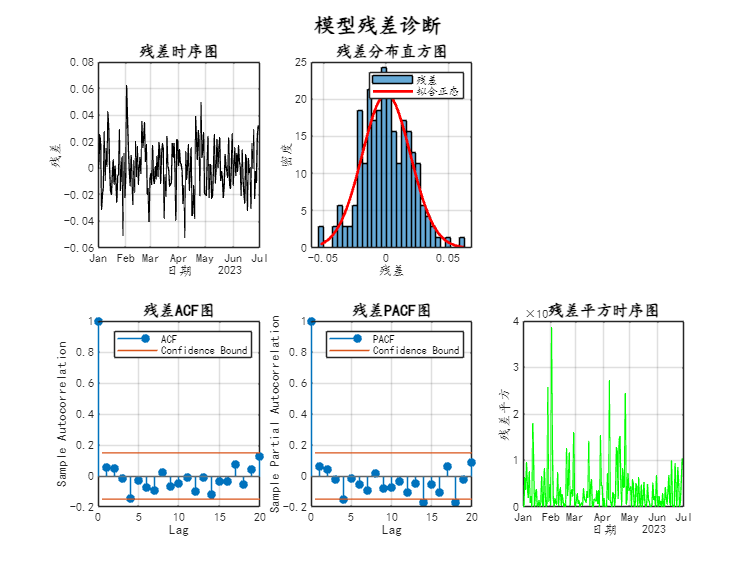


% 计算残差
residuals = infer(EstMdl, stock_data.returns);

% 残差诊断图
figure('Position', [100, 100, 1600, 1200]);

% 残差时序图
subplot(2,3,1);
plot(stock_data.date, residuals, 'k-', 'LineWidth', 1);
title('残差时序图', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('日期');
ylabel('残差');
grid on;

% 残差分布直方图
subplot(2,3,2);
histogram(residuals, 30, 'Normalization', 'pdf');
hold on;
% 叠加正态分布曲线
x_vals = linspace(min(residuals), max(residuals), 100);
pd = fitdist(residuals, 'Normal');
y_vals = pdf(pd, x_vals);
plot(x_vals, y_vals, 'r-', 'LineWidth', 2);
title('残差分布直方图', 'FontSize', 12, 'FontWeight', 'bold');
xlabel('残差');
ylabel('密度');
legend('残差', '拟合正态');
grid on;

% 残差ACF图
subplot(2,3,4);
autocorr(residuals, 'NumLags', 20);
title('残差ACF图', 'FontSize', 12, 'FontWeight', 'bold');
grid on;

% 残差PACF图
subplot(2,3,5);
parcorr(residuals, 'NumLags', 20);
title('残差PACF图', 'FontSize', 12, 'FontWeight', 'bold');
grid on;

% 残差平方的时序图（检验异方差性）
subplot(2,3,6);
plot(stock_data.date, residuals.^2, 'g-', 'LineWidth', 1);
title('残差平方时序图', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('残差平方');
xlabel('日期');
grid on;

sgtitle('模型残差诊断', 'FontSize', 16, 'FontWeight', 'bold');

%% ========== 第八步：模型预测 ==========

fprintf('\n=== 模型预测 ===\n');


=== 模型预测 ===



% 预测步数
forecast_steps = 30;

[yF, yMSE] = forecast(EstMdl, forecast_steps, 'Y0', stock_data.returns);

% 创建预测日期
last_date = stock_data.date(end);
forecast_dates = last_date + days(1:forecast_steps)';

% 计算置信区间
z_value = norminv(0.975); % 95%置信区间
yF_se = sqrt(yMSE);

% 收益率置信区间
yF_ci_lower = yF - z_value * yF_se;
yF_ci_upper = yF + z_value * yF_se;

fprintf('预测完成！\n');

预测完成！


%% ========== 第九步：模型评估 ==========

fprintf('\n=== 模型评估 ===\n');


=== 模型评估 ===



% 创建训练集和验证集（用于评估）
split_point = floor(0.8 * length(stock_data.returns));
train_data = stock_data.returns(1:split_point);
test_data = stock_data.returns(split_point+1:end);

% 如果测试集长度足够，计算预测指标
if length(test_data) >= forecast_steps
    actual_for_eval = test_data(1:forecast_steps);
    
    % 计算预测误差指标
    mae_val = mean(abs(actual_for_eval - yF));
    rmse_val = sqrt(mean((actual_for_eval - yF).^2));
    
    fprintf('模型评估指标:\n');
    fprintf('  MAE: %.6f\n', mae_val);
    fprintf('  RMSE: %.6f\n', rmse_val);
else
    fprintf('测试集数据不足，无法进行完整的模型评估\n');
end

模型评估指标:


  MAE: 0.011934


  RMSE: 0.014786


%% ========== 第十步：结果总结与投资建议 ==========

fprintf('\n=== 结果总结与投资建议 ===\n');


=== 结果总结与投资建议 ===



% 预测总结
avg_predicted_return = mean(yF);
predicted_volatility = std(yF);

fprintf('\n预测总结（未来%d天）:\n', forecast_steps);


预测总结（未来30天）:


fprintf('  平均日收益率预期: %.4f (%.2f%%)\n', avg_predicted_return, avg_predicted_return*100);

  平均日收益率预期: 0.0004 (0.04%)



% 风险评估
var_95 = quantile(yF, 0.05); % 95% VaR
fprintf('\n风险评估:\n');


风险评估:


fprintf('  日VaR(95%%): %.4f (%.2f%%)\n', var_95, var_95*100);

  日VaR(95%): -0.0023 (-0.23%)



% 投资建议
if avg_predicted_return > 0.001 % 日收益率大于0.1%
    recommendation = '买入';
    reason = '模型预测未来收益为正，建议适量买入';
elseif avg_predicted_return < -0.001 % 日收益率小于-0.1%
    recommendation = '卖出';
    reason = '模型预测未来收益为负，建议适量卖出';
else
    recommendation = '持有';
    reason = '模型预测未来收益接近零，建议持有观望';
end

fprintf('\n投资建议: %s\n', recommendation);


投资建议: 持有


fprintf('建议理由: %s\n', reason);

建议理由: 模型预测未来收益接近零，建议持有观望


fprintf('风险提示: 模型基于历史数据，实际结果可能存在差异，请谨慎投资\n');

风险提示: 模型基于历史数据，实际结果可能存在差异，请谨慎投资



%% ========== 错误处理和调试信息 ==========

fprintf('\n=== 调试信息 ===\n');


=== 调试信息 ===


fprintf('数据长度: %d\n', length(stock_data.returns));

数据长度: 180


fprintf('最佳模型参数: ARIMA(%d,%d,%d)\n', best_params(1), best_params(2), best_params(3));

最佳模型参数: ARIMA(2,0,2)



% 检查关键变量是否存在
variables_to_check = {'stock_data', 'EstMdl', 'yF'};
for i = 1:length(variables_to_check)
    if exist(variables_to_check{i}, 'var')
        fprintf('%s 变量已正确初始化\n', variables_to_check{i});
    else
        fprintf('警告: %s 变量未正确初始化\n', variables_to_check{i});
    end
end

stock_data 变量已正确初始化
EstMdl 变量已正确初始化
yF 变量已正确初始化



fprintf('\n%s\n', repmat('=', 1, 60));

fprintf('          ARIMA分析完成！ \n');

          ARIMA分析完成！ 


fprintf('%s\n', repmat('=', 1, 60));